% Goals: Re-familiarize myself with MATLAB

% Vector basics: Instantiation, dot product, transpose 

a = [1, 2, 3, 4]

a =      1     2     3     4


b = [4, 2, 3, 1]

b =      4     2     3     1



c = a.*b

c =      4     4     9     4


d = dot(a, b)

d = 21


t = transpose(a)

t =      1
     2
     3
     4



c = t*b

c =      4     2     3     1
     8     4     6     2
    12     6     9     3
    16     8    12     4


% Testing out pdist()...

a = [0, 2]

a =      0     2


b = [2, 2]

b =      2     2


c = [2, 0]

c =      2     0


d = [0, -2]

d =      0    -2



c = pdist([a;d;a], 'cosine')

c =      2     0     2


% Creating a cardinality function for matrixes...

X = [1, 0, 0, 1; 4, 2, 2, 0; 4, 5, 1, 0]

X =      1     0     0     1
     4     2     2     0
     4     5     1     0



for i = 1:size(X, 2)
    cardinality = sum(X(:,i)~=0);
    fprintf("Cardinality of column i: %d\n", cardinality)
end

Cardinality of column i: 3
Cardinality of column i: 2
Cardinality of column i: 2
Cardinality of column i: 1


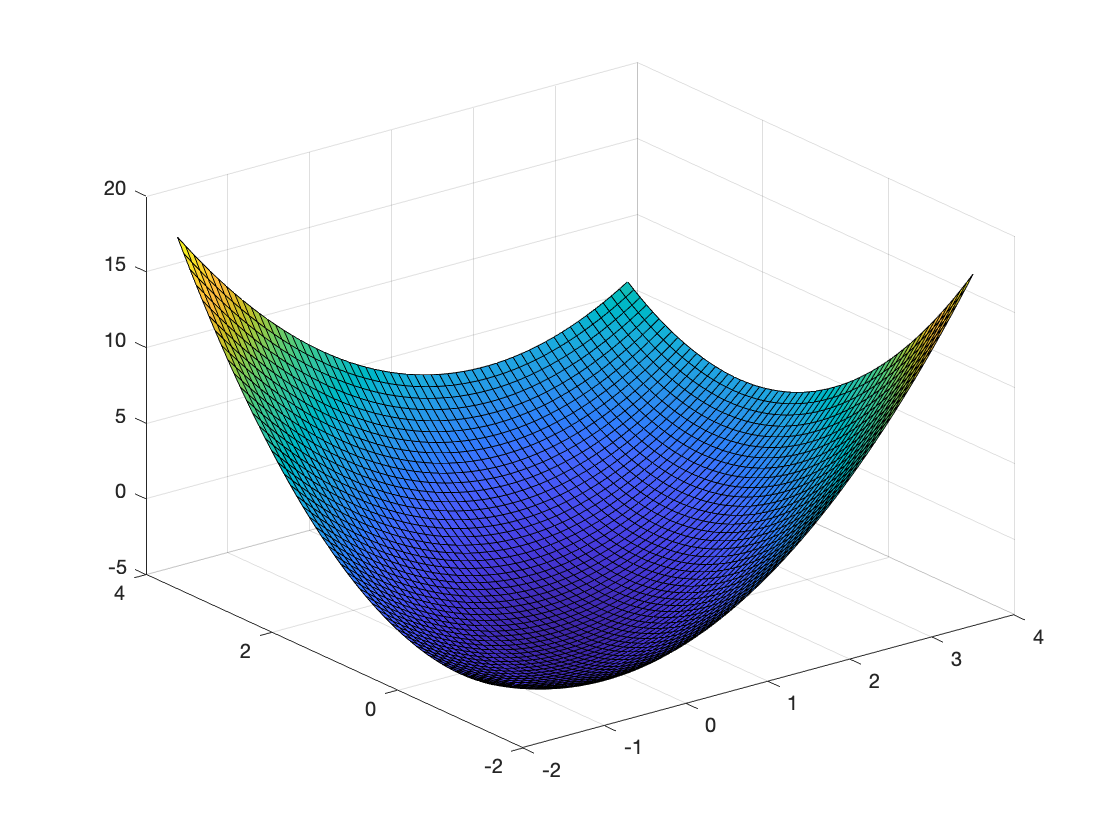

% Figuring out meshgrid, contour

x = -2:.1:3.5;
y = -2:.1:3.5;

[X, Y] = meshgrid(x, y);

f1 = (2*X+3*Y+1);
f2 = X.^2 + Y.^2 - X.*Y - 5;

surf(X, Y, f2);


contour(X, Y, f2)

% How to add in the gradient arrow.
hold on
quiver(1, 1, 1, 1)
hold off

% How to add in line.
y = -1*x + 2

y =     4.0000    3.9000    3.8000    3.7000    3.6000    3.5000    3.4000    3.3000    3.2000    3.1000    3.0000    2.9000    2.8000    2.7000    2.6000    2.5000    2.4000    2.3000    2.2000    2.1000    2.0000    1.9000    1.8000    1.7000    1.6000    1.5000    1.4000    1.3000    1.2000    1.1000    1.0000    0.9000    0.8000    0.7000    0.6000    0.5000    0.4000    0.3000    0.2000    0.1000         0   -0.1000   -0.2000   -0.3000   -0.4000   -0.5000   -0.6000   -0.7000   -0.8000   -0.9000


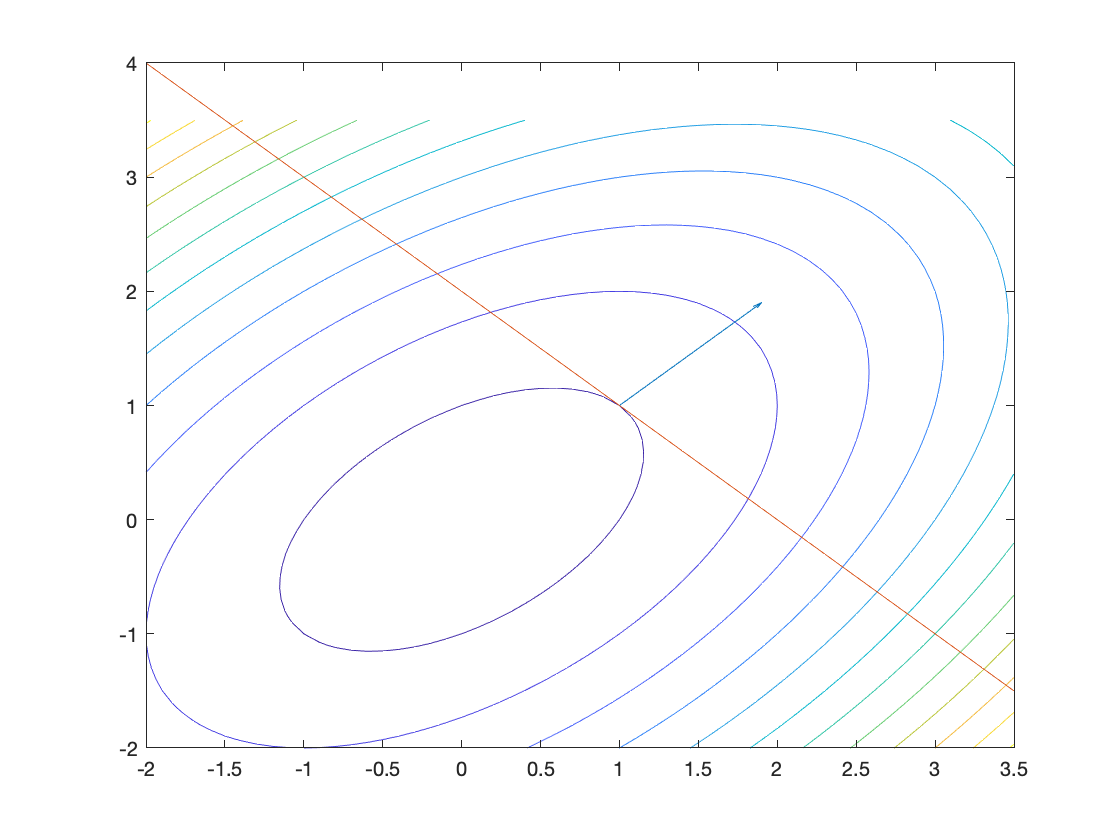


hold on
plot(x, y)
hold off

% c